# Auto-generated by Image Acquisition Explorer

Generated in MATLAB R2023b on 22-Mar-2024 07:13:17

## Connect to Device

Create connection to the device using the specified adaptor with the specified format.

v = videoinput("gentl", 1, "BayerBG8");

## Configure Device Properties

Configure videoinput properties to prepare for acquisition.

v.ReturnedColorspace = "rgb";
v.ROIPosition = [0 0 2064 1544];

## Configure Device-Specific Properties

Configure properties that are specific to this device.

src = getselectedsource(v);
src.AcquisitionFrameRate = 8.575153e+01;

src.ExposureTime = 2.209000e+01;
src.SensorLinePeriod = 7.360000e+00;

## Record Video for Set Number of Frames

Record video data for a specified number of frames.

numFrames = 10;
v.FramesPerTrigger = numFrames;

start(v);

wait(v);
stop(v);
recording1 = getdata(v, numFrames);

## Show Recording

View the recorded video.

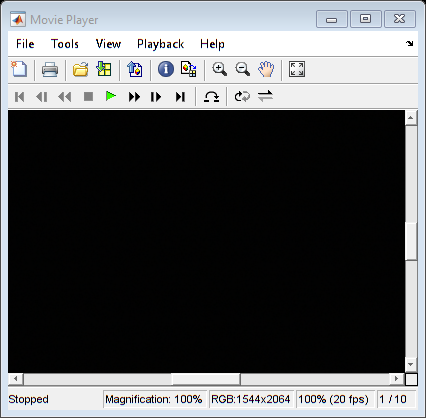

implay(recording1);

## Clean Up

Delete the videoinput object and clear variables from the workspace.

%delete(v)
%clear src v